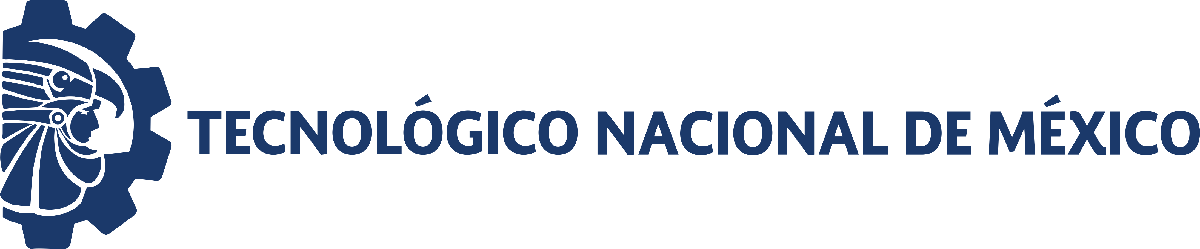                                 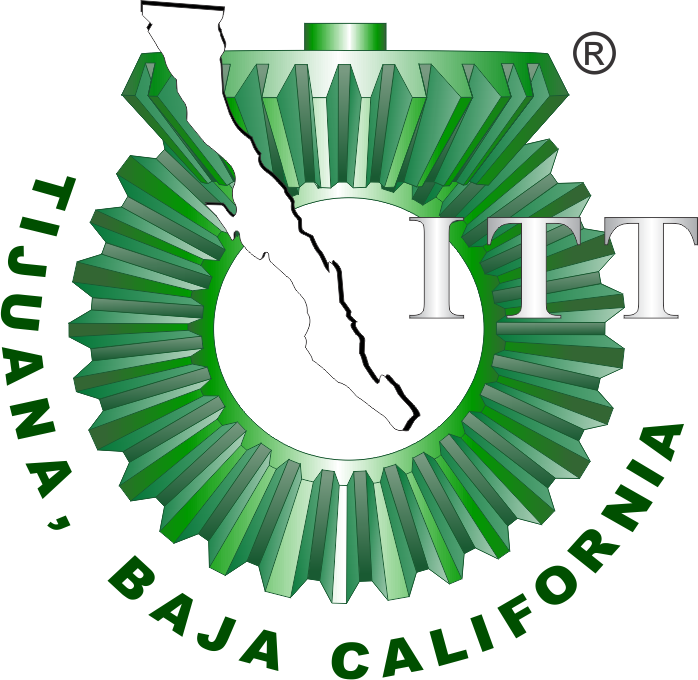

# Práctica: Modelado y control del sistema musculoesquelético 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

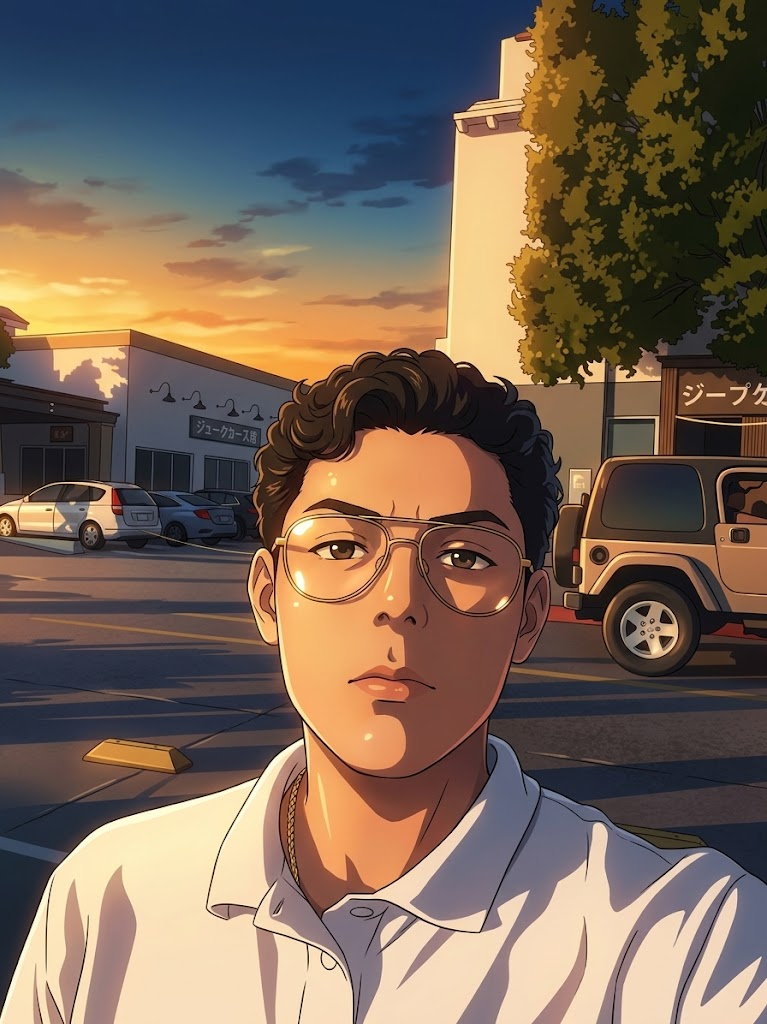

Nombre del alumno: **Christian** **Cid Pacheco**

Número de control: **23212186**

Correo institucional:** l23212186@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al impulso unitario

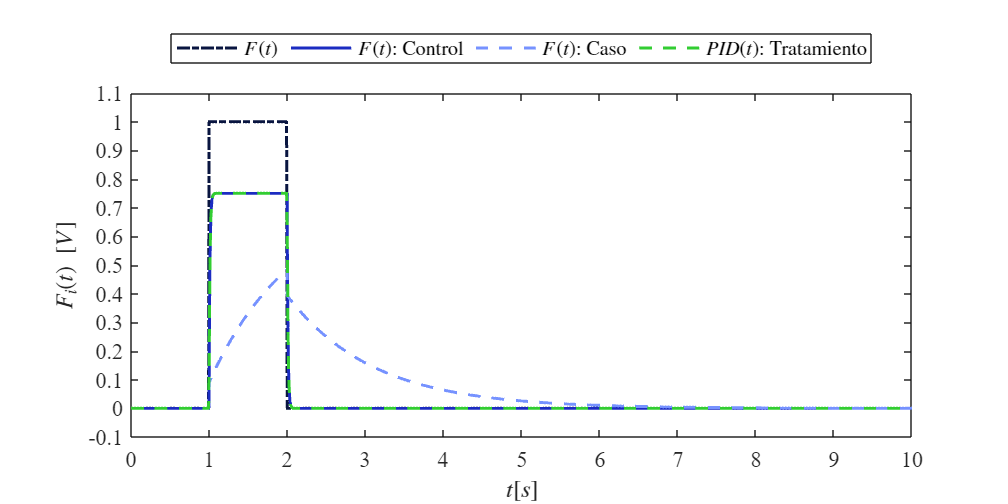

x = sim('sistema.slx',parameters);
plotsignals(x.t, x.F, x.Fsx, x.Fsy, x.PID, 'Caso');

## Funcion: Respuestas de la simulacion

function plotsignals(t, F, Fsx, Fsy, PID, signal)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'inches', 'position', [1, 1, 7, 3.5])
    set(gca, 'fontname', 'times new roman', 'fontsize', 11)
    hold on; grid off; box on;
    clr1 = [9, 21, 64]/255;
    clr2 = [27, 44, 193]/255;
    clr3 = [118, 146, 255]/255;
    clr4 = [50, 205, 50]/255;   
    order = [clr1; clr2; clr3; clr4]; 
    colororder(order)

    if signal == "Caso"
        plot( t, F, '-.', t, Fsx, '-', t, Fsy, '--', t, PID, '--',  ...
            'LineWidth', 1.5, 'MarkerSize', 5);
        L = legend('$F(t)$', '$F(t)$: Control', '$F(t)$: Caso', '$PID(t)$: Tratamiento');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t[s]$','interpreter','latex')
    ylabel('$F_i(t)\ [V]$','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')
end